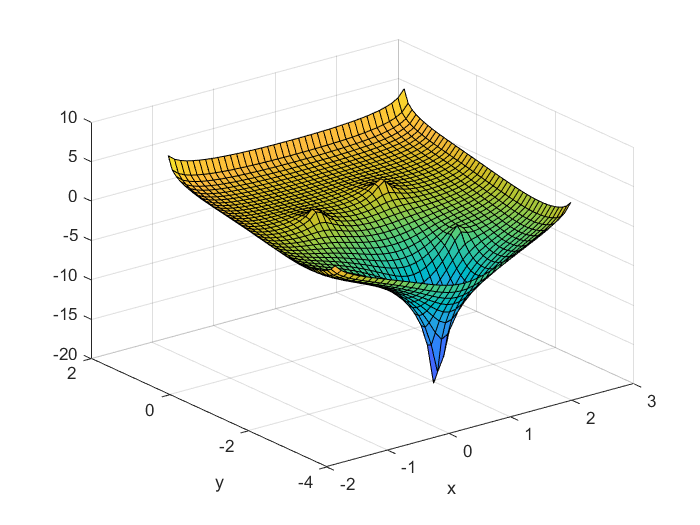

%Create the meshgrid
[x,y] = meshgrid(-1.5:(sqrt(2)/14):2.5, -3.37:(sqrt(2)/14):1);

%Create sinks for the walls
Wall_1 = log(sqrt((y-1).^2));
Wall_2 = log(sqrt((y+3.37).^2));
wall_3 = log(sqrt((x+1.5).^2));
wall_4 = log(sqrt((x-2.5).^2));

%Create sinks for the squares
Square_1 = log(sqrt((x+.25).^2+(y+1).^2));
Square_2 = log(sqrt((x-1).^2+(y+0.7).^2));
Square_3 = log(sqrt((x-1.4).^2+(y+2).^2));

%Create Barrel but also scale it by a factor of 5
BoB = 5*log(sqrt((x-0.75).^2+(y+2.5).^2));

%Add the equations together
V = -(Wall_1+Wall_2+wall_3+wall_4+Square_1+Square_2+Square_3-BoB);

%Visualize the plot (Surface and contour)
surf(x,y,V)
xlabel("x")
ylabel('y')

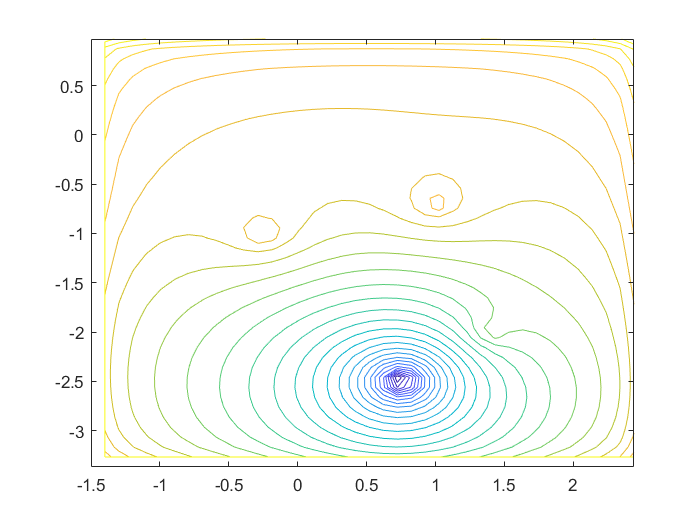

contour(x,y,V,30)

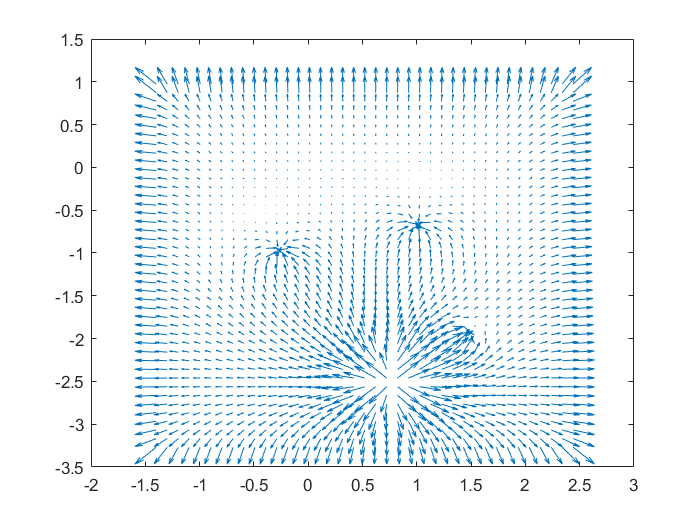


%Develop the gradient from the equation remove points that head towards
%infinity
[gradx, grady] = gradient(V, 0.11);
gradx(gradx > 1e+1) = 1e+1; gradx(gradx < -1e+1) = -1e+1; 
grady(grady > 1e+1) = 1e+1; grady(grady < -1e+1) = -1e+1; 

%Visualize gradient
quiver(x,y,gradx,grady,2)

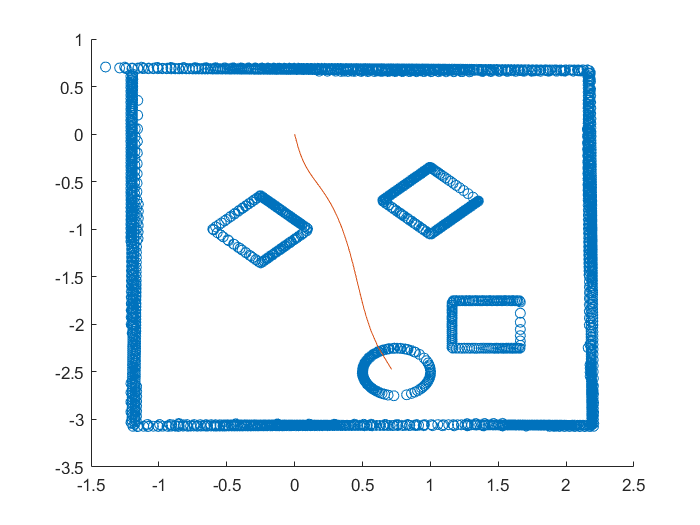

%Symbolically recreate the equation
syms x y 

Wall_1 = log(sqrt((y-1).^2));
Wall_2 = log(sqrt((y+3.37).^2));
wall_3 = log(sqrt((x+1.5).^2));
wall_4 = log(sqrt((x-2.5).^2));

Square_1 = log(sqrt((x+.25).^2+(y+1).^2));
Square_2 = log(sqrt((x-1).^2+(y+0.7).^2));
Square_3 = log(sqrt((x-1.4).^2+(y+2).^2));
 
BoB = 5*log(sqrt((x-0.75).^2+(y+2.5).^2));
V1 = -(Wall_1+Wall_2+wall_3+wall_4+Square_1+Square_2+Square_3-BoB);

%Convert the symbolic into a function handel 
g = matlabFunction(gradient(V1));

%Perform gradient descent
position = gradient_descent(g,[0 0],0.9,0.15,20,200);

%Create the plot of the gauntlet
load Cartesians.mat
[i,j] = meshgrid(-1.5:(sqrt(2)/14):2.5, -3.37:(sqrt(2)/14):1);
points = sortrows(transpose(all_points));

%Visualize the gradient ascent on the plot
figure()
hold on
scatter(points(:,1),points(:,2))
plot(position(:,1),position(:,2))


%Export the equation to be used in simulation
save('Equation.mat','V1')

d = 0.2350

left_x =     0.1563
    0.1587
    0.1610
    0.1636
    0.1836
    0.2036
    0.2236
    0.2434
    0.2412
    0.2612


right_x =    -0.1587
   -0.1610
   -0.1634
   -0.1656
   -0.1456
   -0.1256
   -0.1056
   -0.0858
   -0.0832
   -0.0632


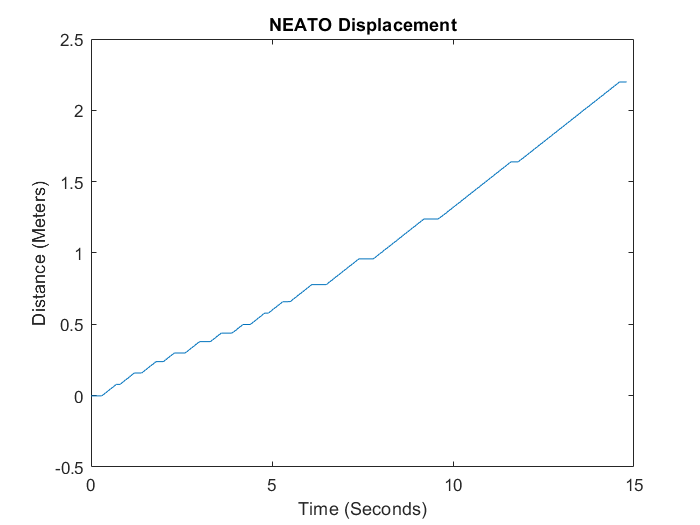

calc_r =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0